# For the prelab

Encode from a table

ftable = [1;2;3;4;5]*[80,110]

ftable =     80   110
   160   220
   240   330
   320   440
   400   550


fs = 8000;
xx = [ ];
disp('--- Here we go through the Loop ---')

--- Here we go through the Loop ---


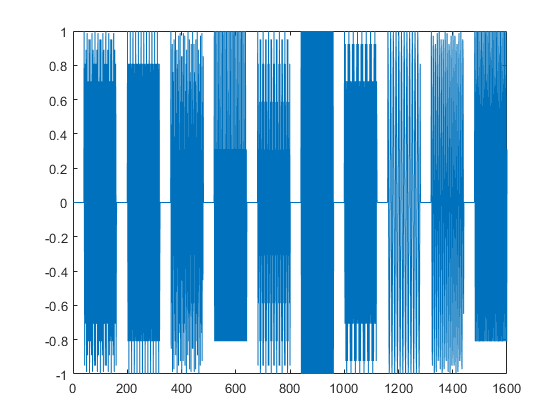

keys = rem(3:12,10) + 1;
for ii = 1:length(keys)
    kk = keys(ii);
    xx = [xx,zeros(1,400)];
    krow = ceil(kk/2);
    kcol = rem(kk-1,2) + 1;
    xx = [xx, cos(2*pi*ftable(krow,kcol)*(0:1199)/fs) ];
end
soundsc(xx,fs);
% Downsample and plot the results
xxd = downsample(xx, 10);
figure
plot(xxd);

Overlay plotting Get the 160-points frequency respond 

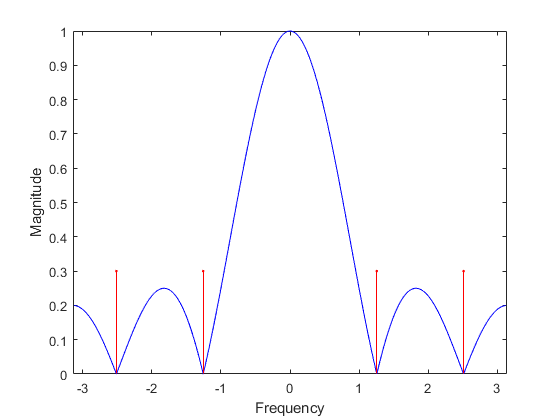

[h,w]=freqz(ones(1,5)/5,1,160);
plot(w,(abs(h)),'b');
hold on
% Use the symetric features to extend response to range [-pi pi]
plot(-w,(abs(h)),'b');
xlim ([-pi pi]) ;
xlabel('Frequency')
ylabel('Magnitude')
% Find the zeros
hold on, stem(2*pi/5*[-2,-1,1,2],0.3*ones(1,4),'r.'), hold off

Test dtmfdial.m

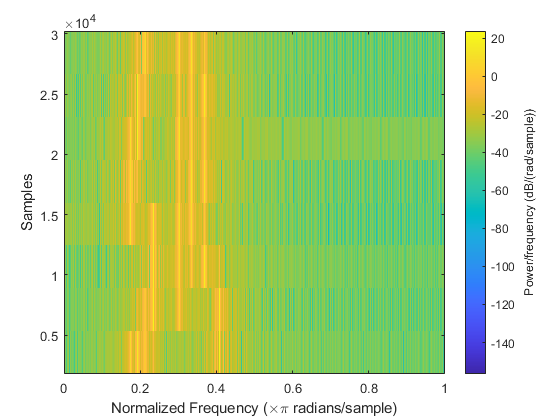

fs = 8000;
L1 = 40;
tk1 = ['A','B','C','D','*','#','0','1','2','3','4','5','6','7','8','9'];
xx = dtmfdial(tk1, fs);
soundsc(xx, fs);
figure
spectrogram(xx);

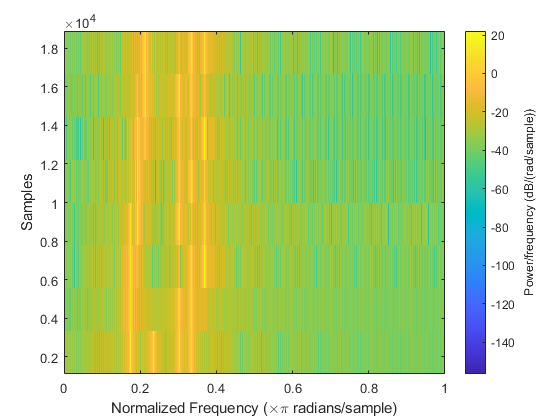


tk2 = ['0','1','2','3','4','5','6','7','8','9'];
xx = dtmfdial(tk2, fs);
soundsc(xx, fs);
figure
spectrogram(xx);

Simple bandpass filter design

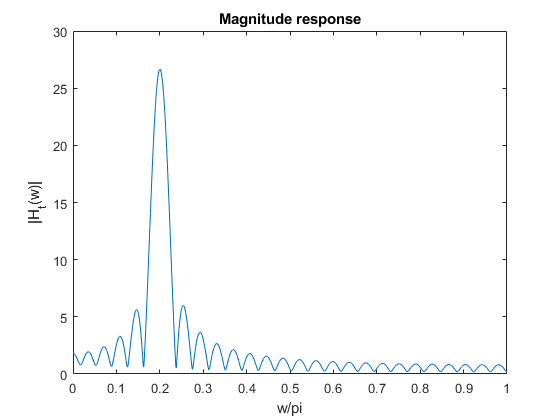

L=51;n=0:1:L;
wc=0.2*pi;
h=(cos(wc*n));
k=0;
for w=0:pi/1000:pi
    k=k+1;
    H_t(k)=sum(h.*exp(-j*w*n));
end
w=0:pi/1000:pi;
figure
plot(w/pi,abs(H_t))
xlabel('w/pi')
ylabel('|H_t(w)|')
title('Magnitude response')

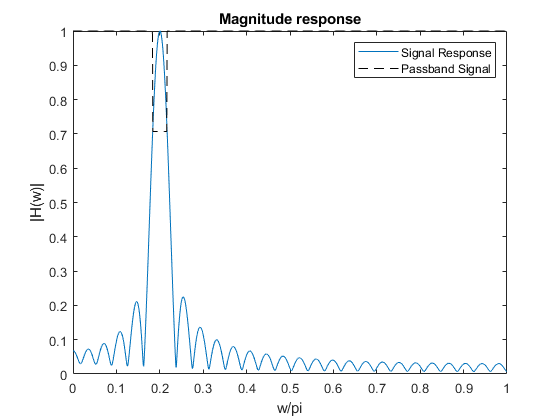

beta = 1/max(abs(H_t));
k =0;
for w=0:pi/1000:pi
    k=k+1;
    H(k)=sum(beta* h.*exp(-j*w*n));
end
w=0:pi/1000:pi;

Hmax=max(abs(H));
wb=w(find(abs(H)>=0.707*Hmax));
H_bp=(Hmax.*(w>=min(w) & w<wb(1)))+(0.707*Hmax.*(w>=wb(1) &w<=wb(end)))+(Hmax.*(w>wb(end) & w<=max(w)));
figure
plot(w/pi,abs(H));title('Magnitude response');xlabel('w/pi');ylabel('|H(w)|')
hold on;
plot(w/pi,H_bp,'--k');
legend('Signal Response','Passband Signal')

Find the passband bound

boundL = min(wb)/pi;
boundU = max(wb)/pi;
OmegaL = fs * boundL;
OmegaU = fs * boundU;
OmegaC = fs * 0.2;
pass = ['---Passband frequency is from ',num2str(OmegaL),' pi to ', num2str(OmegaU),' pi.---'];
disp(pass);

---Passband frequency is from 1472 pi to 1728 pi.---



center = ['---Central frequency is ',num2str(OmegaC),' pi.---'];
disp(center);

---Central frequency is 1600 pi.---


## For the lab test

Test for dtmfdesign.m

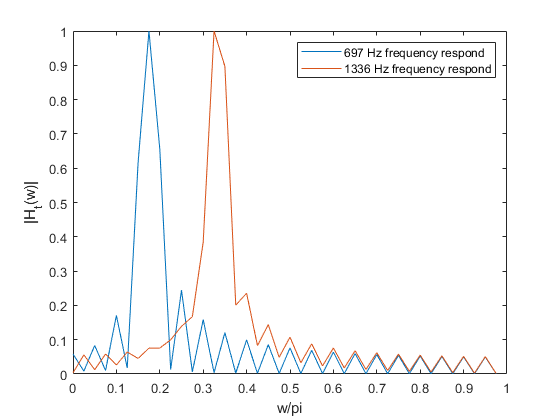

L1 = 40;
fs = 8000;
freq1 = [697 1336];
hh1 = dtmfdesign2(freq1, L1, fs);
w=0:pi/L1:(pi-1/L1);
figure
plot(w/pi,abs(hh1));
xlabel('w/pi')
ylabel('|H_t(w)|')
legend('697 Hz frequency respond','1336 Hz frequency respond')

disp('- We use two frequncy as input and it shows passband is narrow enough to separate the signal.-') 

- We use two frequncy as input and it shows passband is narrow enough to separate the signal.-


disp('- Then we try to use all 8 frequency as input. -')

- Then we try to use all 8 frequency as input. -


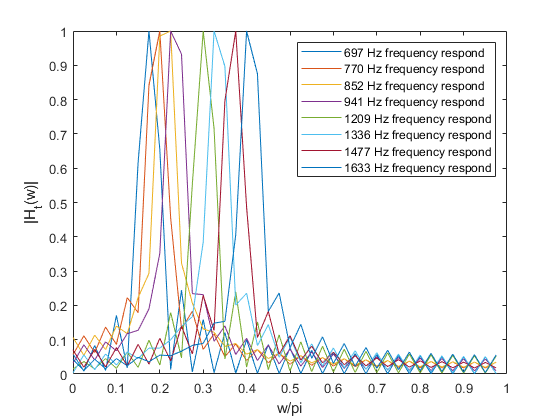


freq2 = [697 770 852 941 1209 1336 1477 1633];
hh2 = dtmfdesign2(freq2, L1, fs);
w=0:pi/L1:(pi-1/L1);
figure
plot(w/pi,abs(hh2));
xlabel('w/pi')
ylabel('|H_t(w)|')
legend('697 Hz frequency respond','770 Hz frequency respond','852 Hz frequency respond','941 Hz frequency respond','1209 Hz frequency respond','1336 Hz frequency respond','1477 Hz frequency respond','1633 Hz frequency respond')

disp('- Frequency are not separable for they are overlapping.-')

- Frequency are not separable for they are overlapping.-


disp('- We adjust the L to 80. -')

- We adjust the L to 80. -


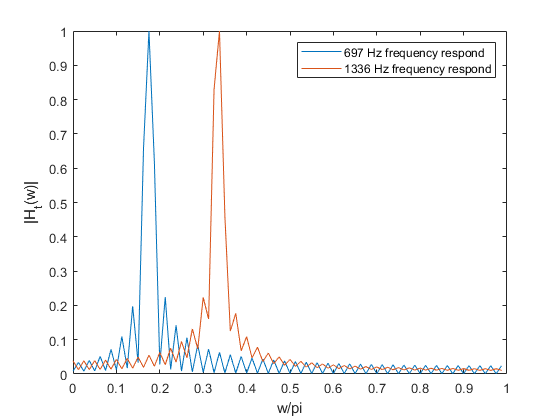

L2 = 80;
freq1 = [697 1336];
hh1 = dtmfdesign2(freq1, L2, fs);
w=0:pi/L2:(pi -pi/L2);
figure
plot(w/pi,abs(hh1));
ylim([0 1]);
xlabel('w/pi')
ylabel('|H_t(w)|')
legend('697 Hz frequency respond','1336 Hz frequency respond')

disp('- By comparison, we find the frequency response become more narrow when L increases.-') 

- By comparison, we find the frequency response become more narrow when L increases.-


disp('- The width of passband varies inversely with filter length. -')

- The width of passband varies inversely with filter length. -


disp('- Then we try to use all 8 frequency as input. -')

- Then we try to use all 8 frequency as input. -


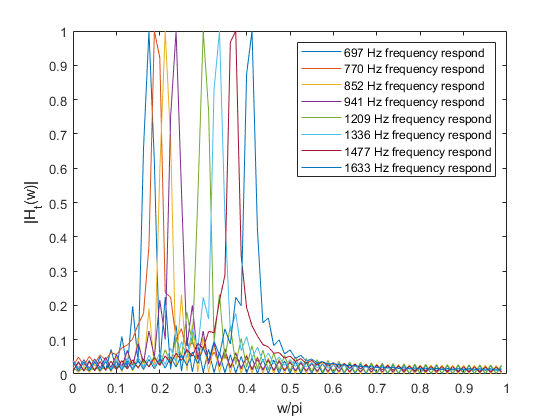


freq2 = [697 770 852 941 1209 1336 1477 1633];
hh2 = dtmfdesign2(freq2, L2, fs);
w=0:pi/L2:(pi-pi/L2);
figure
plot(w/pi,abs(hh2));
ylim([0 1]);
xlabel('w/pi')
ylabel('|H_t(w)|')
legend('697 Hz frequency respond','770 Hz frequency respond','852 Hz frequency respond','941 Hz frequency respond','1209 Hz frequency respond','1336 Hz frequency respond','1477 Hz frequency respond','1633 Hz frequency respond')

disp('- Frequency response are more narrow.-')

- Frequency response are more narrow.-


Test for dtmfscore.m

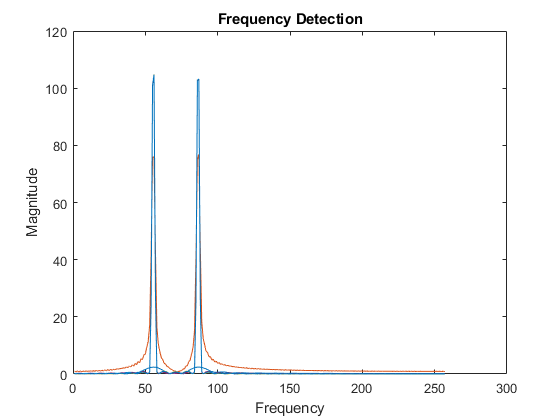

L1 = 40;
fs = 8000;
xx= [];
xx = dtmfdial(['8'],fs);
%xx1 = xx(200:length(xx));
xxs = spectrogram(xx);
figure
plot(abs(xxs));
xlabel('Frequency')
ylabel('Magnitude')
title('Frequency Detection')


hh = [];
hh2 = [];
freq2 = [697 770 852 941 1209 1336 1477 1633];
hh = dtmfdesign(freq2, L1, fs);
hh2 = dtmfdesign2(freq2, L1, fs);
yy = conv(xx,hh(:,3));
y1 = max(yy);
sc = [];
for i = 1:size(hh,2)
    sc(i) = dtmfscore2(xx, hh(:,i));
    
end

Final Test

fs = 8000;
L2 = 80;
tk = ['A','B','C','D','*','#','0','1','2','3','4','5','6','7','8','9'];
xx = dtmfdial(tk, fs);
soundsc(xx, fs)
keys = dtmfrun(xx, L2, fs);